# Extract and Display Image Decomposition Level

This example shows how to extract and display images of wavelet decomposition level details.

Load an image. Perform a level 2 wavelet decomposition of the image using the `haar` wavelet.

%https://it.mathworks.com/matlabcentral/answers/54439-list-of-builtin-demo-images

load woman
% family='db1';
% family='sym2';
family='haar';
[c,s]=wavedec2(X,4,family);

Extract the level 1 approximation and detail coefficients.

[H1,V1,D1] = detcoef2('all',c,s,1);
A1 = appcoef2(c,s,family,1);

Use `wcodemat` to rescale the coefficients based on their absolute values. Display the rescaled coefficients.

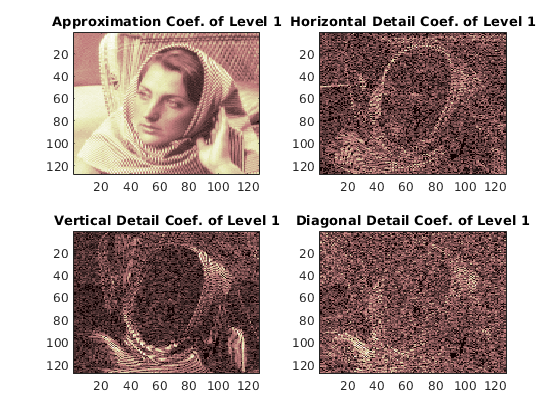

V1img = wcodemat(V1,255,'mat',1);
H1img = wcodemat(H1,255,'mat',1);
D1img = wcodemat(D1,255,'mat',1);
A1img = wcodemat(A1,255,'mat',1);

subplot(2,2,1)
imagesc(A1img)
colormap pink(255)
title('Approximation Coef. of Level 1')

subplot(2,2,2)
imagesc(H1img)
title('Horizontal Detail Coef. of Level 1')

subplot(2,2,3)
imagesc(V1img)
title('Vertical Detail Coef. of Level 1')

subplot(2,2,4)
imagesc(D1img)
title('Diagonal Detail Coef. of Level 1')

Extract the level 2 approximation and detail coefficients.

[H2,V2,D2] = detcoef2('all',c,s,2);
A2 = appcoef2(c,s,family,2);

Use `wcodemat` to rescale the coefficients based on their absolute values. Display the rescaled coefficients.

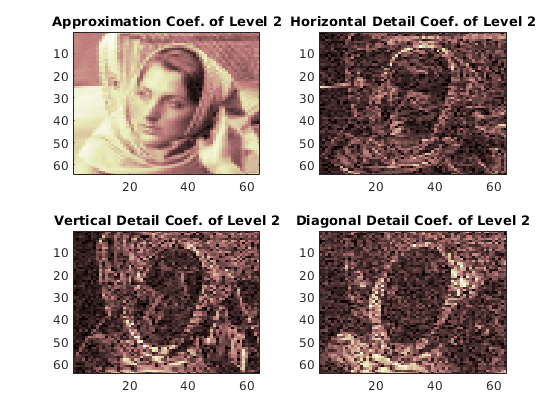

V2img = wcodemat(V2,255,'mat',1);
H2img = wcodemat(H2,255,'mat',1);
D2img = wcodemat(D2,255,'mat',1);
A2img = wcodemat(A2,255,'mat',1);

figure
subplot(2,2,1)
imagesc(A2img)
colormap pink(255)
title('Approximation Coef. of Level 2')

subplot(2,2,2)
imagesc(H2img)
title('Horizontal Detail Coef. of Level 2')

subplot(2,2,3)
imagesc(V2img)
title('Vertical Detail Coef. of Level 2')

subplot(2,2,4)
imagesc(D2img)
title('Diagonal Detail Coef. of Level 2')

*Copyright 2012 The MathWorks, Inc.*

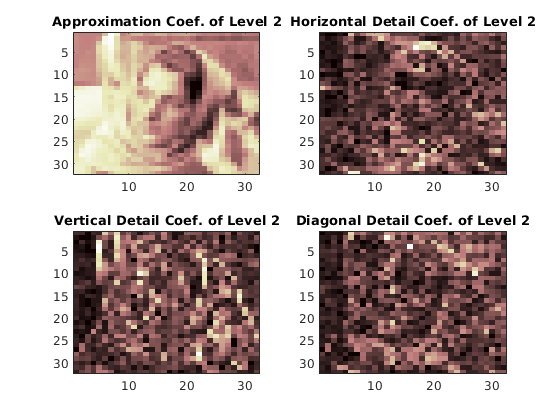

[H3,V3,D3] = detcoef2('all',c,s,3);
A3 = appcoef2(c,s,family,3);


V3img = wcodemat(V3,255,'mat',1);
H3img = wcodemat(H3,255,'mat',1);
D3img = wcodemat(D3,255,'mat',1);
A3img = wcodemat(A3,255,'mat',1);

figure
subplot(2,2,1)
imagesc(A3img)
colormap pink(255)
title('Approximation Coef. of Level 2')

subplot(2,2,2)
imagesc(H3img)
title('Horizontal Detail Coef. of Level 2')

subplot(2,2,3)
imagesc(V3img)
title('Vertical Detail Coef. of Level 2')

subplot(2,2,4)
imagesc(D3img)
title('Diagonal Detail Coef. of Level 2')